syms t

my_eta = 0.1

my_eta = 0.1000

wn = 2;
wd = wn*sqrt(1 - my_eta^2);
y = 3*exp(-my_eta*wn*t)*sin(wd*t)  + 0.005*t^2

$$y = 3\,{\mathrm{e}}^{-\frac{t}{5}}\,\sin\left(\frac{3\,\sqrt{11}\,t}{5}\right)+\frac{t^{2}}{200}$$

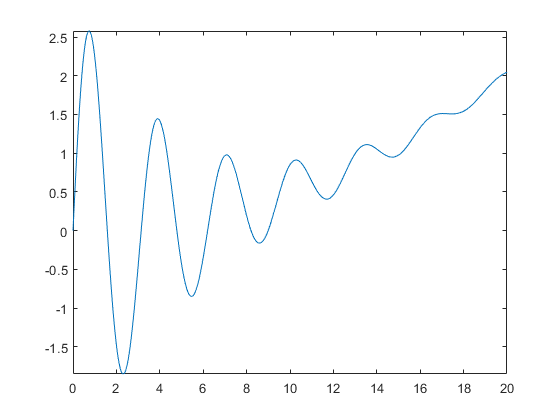


fplot(y, [0 20])


yd = diff(y,t)

$$yd = \frac{t}{100}-\frac{3\,{\mathrm{e}}^{-\frac{t}{5}}\,\sin\left(\frac{3\,\sqrt{11}\,t}{5}\right)}{5}+\frac{9\,\sqrt{11}\,{\mathrm{e}}^{-\frac{t}{5}}\,\cos\left(\frac{3\,\sqrt{11}\,t}{5}\right)}{5}$$


ydd = diff(y,t,2)

$$ydd = \frac{1}{100}-\frac{18\,\sqrt{11}\,{\mathrm{e}}^{-\frac{t}{5}}\,\cos\left(\frac{3\,\sqrt{11}\,t}{5}\right)}{25}-\frac{294\,{\mathrm{e}}^{-\frac{t}{5}}\,\sin\left(\frac{3\,\sqrt{11}\,t}{5}\right)}{25}$$

Create a MATLAb Function block

if(true)
    MODEL_NAME = 'bh_tmp_model_WILL_BE_DELETED';
    if(4==exist(MODEL_NAME))
        close_system(MODEL_NAME, 0);
        delete(MODEL_NAME);
    end
    new_system(MODEL_NAME)
    open_system(MODEL_NAME)      
    %-------------------------------------------------------
    % Create a block that computes A and b
    matlabFunctionBlock( [MODEL_NAME,'/TRUE_y_yd_ydd'], y,yd, ydd);
    
end       